# Create Deep Learning Network Architecture with Pretrained Parameters

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable `lgraph`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 2021-07-09 03:08:02

## Load the Pretrained Parameters

params = load("C:\Users\12424\Desktop\Acadimic\Computer Science\Master 1\Research Methodology Computer Science\Project\params_2021_08_07__11_21_16.mat");

## Import Data

Import training and validation data.

imds = imageDatastore("C:\Users\12424\Desktop\Acadimic\Computer Science\Master 1\Research Methodology Computer Science\Project\Dataset","IncludeSubfolders",true,"LabelSource","foldernames");
[imdsTrain, imdsValidation] = splitEachLabel(imds, 0.7, 'randomized');

% Resize the images to match the network input layer.
augimdsTrain = augmentedImageDatastore([224 224 3],imdsTrain,'ColorPreprocessing',"gray2rgb");
augimdsValidation = augmentedImageDatastore([224 224 3],imdsValidation,"ColorPreprocessing","gray2rgb");

## Set Training Options

Specify options to use when training.

opts = trainingOptions("sgdm",...
    "ExecutionEnvironment","gpu",...
    "InitialLearnRate",0.001,...
    "LearnRateDropPeriod",5,...
    "MaxEpochs",20,...
    "MiniBatchSize",20,...
    "Momentum",0,...
    "Shuffle","every-epoch",...
    "ValidationFrequency",4000,...
    "Plots","training-progress",...
    "ValidationData",augimdsValidation);

## Create Layer Graph

Create the layer graph variable to contain the network layers.

lgraph = layerGraph();

## Add Layer Branches

Add the branches of the network to the layer graph. Each branch is a linear array of layers.

tempLayers = [
    imageInputLayer([224 224 3],"Name","data","Mean",params.data.Mean)
    convolution2dLayer([7 7],64,"Name","conv1-7x7_s2","BiasLearnRateFactor",2,"Padding",[3 3 3 3],"Stride",[2 2],"Bias",params.conv1_7x7_s2.Bias,"Weights",params.conv1_7x7_s2.Weights)
    reluLayer("Name","conv1-relu_7x7")
    maxPooling2dLayer([3 3],"Name","pool1-3x3_s2","Padding",[0 1 0 1],"Stride",[2 2])
    crossChannelNormalizationLayer(5,"Name","pool1-norm1","K",1)
    convolution2dLayer([1 1],64,"Name","conv2-3x3_reduce","BiasLearnRateFactor",2,"Bias",params.conv2_3x3_reduce.Bias,"Weights",params.conv2_3x3_reduce.Weights)
    reluLayer("Name","conv2-relu_3x3_reduce")
    convolution2dLayer([3 3],192,"Name","conv2-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1],"Bias",params.conv2_3x3.Bias,"Weights",params.conv2_3x3.Weights)
    reluLayer("Name","conv2-relu_3x3")
    crossChannelNormalizationLayer(5,"Name","conv2-norm2","K",1)
    maxPooling2dLayer([3 3],"Name","pool2-3x3_s2","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],16,"Name","inception_3a-5x5_reduce","BiasLearnRateFactor",2,"Bias",params.inception_3a_5x5_reduce.Bias,"Weights",params.inception_3a_5x5_reduce.Weights)
    reluLayer("Name","inception_3a-relu_5x5_reduce")
    convolution2dLayer([5 5],32,"Name","inception_3a-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2],"Bias",params.inception_3a_5x5.Bias,"Weights",params.inception_3a_5x5.Weights)
    reluLayer("Name","inception_3a-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],96,"Name","inception_3a-3x3_reduce","BiasLearnRateFactor",2,"Bias",params.inception_3a_3x3_reduce.Bias,"Weights",params.inception_3a_3x3_reduce.Weights)
    reluLayer("Name","inception_3a-relu_3x3_reduce")
    convolution2dLayer([3 3],128,"Name","inception_3a-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1],"Bias",params.inception_3a_3x3.Bias,"Weights",params.inception_3a_3x3.Weights)
    reluLayer("Name","inception_3a-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_3a-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],32,"Name","inception_3a-pool_proj","BiasLearnRateFactor",2,"Bias",params.inception_3a_pool_proj.Bias,"Weights",params.inception_3a_pool_proj.Weights)
    reluLayer("Name","inception_3a-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],64,"Name","inception_3a-1x1","BiasLearnRateFactor",2,"Bias",params.inception_3a_1x1.Bias,"Weights",params.inception_3a_1x1.Weights)
    reluLayer("Name","inception_3a-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_3a-output");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_3b-1x1","BiasLearnRateFactor",2,"Bias",params.inception_3b_1x1.Bias,"Weights",params.inception_3b_1x1.Weights)
    reluLayer("Name","inception_3b-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_3b-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_3b-pool_proj","BiasLearnRateFactor",2,"Bias",params.inception_3b_pool_proj.Bias,"Weights",params.inception_3b_pool_proj.Weights)
    reluLayer("Name","inception_3b-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_3b-3x3_reduce","BiasLearnRateFactor",2,"Bias",params.inception_3b_3x3_reduce.Bias,"Weights",params.inception_3b_3x3_reduce.Weights)
    reluLayer("Name","inception_3b-relu_3x3_reduce")
    convolution2dLayer([3 3],192,"Name","inception_3b-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1],"Bias",params.inception_3b_3x3.Bias,"Weights",params.inception_3b_3x3.Weights)
    reluLayer("Name","inception_3b-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_3b-5x5_reduce","BiasLearnRateFactor",2,"Bias",params.inception_3b_5x5_reduce.Bias,"Weights",params.inception_3b_5x5_reduce.Weights)
    reluLayer("Name","inception_3b-relu_5x5_reduce")
    convolution2dLayer([5 5],96,"Name","inception_3b-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2],"Bias",params.inception_3b_5x5.Bias,"Weights",params.inception_3b_5x5.Weights)
    reluLayer("Name","inception_3b-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_3b-output")
    maxPooling2dLayer([3 3],"Name","pool3-3x3_s2","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],16,"Name","inception_4a-5x5_reduce","BiasLearnRateFactor",2,"Bias",params.inception_4a_5x5_reduce.Bias,"Weights",params.inception_4a_5x5_reduce.Weights)
    reluLayer("Name","inception_4a-relu_5x5_reduce")
    convolution2dLayer([5 5],48,"Name","inception_4a-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2],"Bias",params.inception_4a_5x5.Bias,"Weights",params.inception_4a_5x5.Weights)
    reluLayer("Name","inception_4a-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],96,"Name","inception_4a-3x3_reduce","BiasLearnRateFactor",2,"Bias",params.inception_4a_3x3_reduce.Bias,"Weights",params.inception_4a_3x3_reduce.Weights)
    reluLayer("Name","inception_4a-relu_3x3_reduce")
    convolution2dLayer([3 3],208,"Name","inception_4a-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1],"Bias",params.inception_4a_3x3.Bias,"Weights",params.inception_4a_3x3.Weights)
    reluLayer("Name","inception_4a-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4a-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4a-pool_proj","BiasLearnRateFactor",2,"Bias",params.inception_4a_pool_proj.Bias,"Weights",params.inception_4a_pool_proj.Weights)
    reluLayer("Name","inception_4a-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],192,"Name","inception_4a-1x1","BiasLearnRateFactor",2,"Bias",params.inception_4a_1x1.Bias,"Weights",params.inception_4a_1x1.Weights)
    reluLayer("Name","inception_4a-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4a-output");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],112,"Name","inception_4b-3x3_reduce","BiasLearnRateFactor",2,"Bias",params.inception_4b_3x3_reduce.Bias,"Weights",params.inception_4b_3x3_reduce.Weights)
    reluLayer("Name","inception_4b-relu_3x3_reduce")
    convolution2dLayer([3 3],224,"Name","inception_4b-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1],"Bias",params.inception_4b_3x3.Bias,"Weights",params.inception_4b_3x3.Weights)
    reluLayer("Name","inception_4b-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_4b-1x1","BiasLearnRateFactor",2,"Bias",params.inception_4b_1x1.Bias,"Weights",params.inception_4b_1x1.Weights)
    reluLayer("Name","inception_4b-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],24,"Name","inception_4b-5x5_reduce","BiasLearnRateFactor",2,"Bias",params.inception_4b_5x5_reduce.Bias,"Weights",params.inception_4b_5x5_reduce.Weights)
    reluLayer("Name","inception_4b-relu_5x5_reduce")
    convolution2dLayer([5 5],64,"Name","inception_4b-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2],"Bias",params.inception_4b_5x5.Bias,"Weights",params.inception_4b_5x5.Weights)
    reluLayer("Name","inception_4b-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4b-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4b-pool_proj","BiasLearnRateFactor",2,"Bias",params.inception_4b_pool_proj.Bias,"Weights",params.inception_4b_pool_proj.Weights)
    reluLayer("Name","inception_4b-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4b-output");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_4c-1x1","BiasLearnRateFactor",2,"Bias",params.inception_4c_1x1.Bias,"Weights",params.inception_4c_1x1.Weights)
    reluLayer("Name","inception_4c-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4c-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4c-pool_proj","BiasLearnRateFactor",2,"Bias",params.inception_4c_pool_proj.Bias,"Weights",params.inception_4c_pool_proj.Weights)
    reluLayer("Name","inception_4c-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","inception_4c-3x3_reduce","BiasLearnRateFactor",2,"Bias",params.inception_4c_3x3_reduce.Bias,"Weights",params.inception_4c_3x3_reduce.Weights)
    reluLayer("Name","inception_4c-relu_3x3_reduce")
    convolution2dLayer([3 3],256,"Name","inception_4c-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1],"Bias",params.inception_4c_3x3.Bias,"Weights",params.inception_4c_3x3.Weights)
    reluLayer("Name","inception_4c-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],24,"Name","inception_4c-5x5_reduce","BiasLearnRateFactor",2,"Bias",params.inception_4c_5x5_reduce.Bias,"Weights",params.inception_4c_5x5_reduce.Weights)
    reluLayer("Name","inception_4c-relu_5x5_reduce")
    convolution2dLayer([5 5],64,"Name","inception_4c-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2],"Bias",params.inception_4c_5x5.Bias,"Weights",params.inception_4c_5x5.Weights)
    reluLayer("Name","inception_4c-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4c-output");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4d-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],64,"Name","inception_4d-pool_proj","BiasLearnRateFactor",2,"Bias",params.inception_4d_pool_proj.Bias,"Weights",params.inception_4d_pool_proj.Weights)
    reluLayer("Name","inception_4d-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_4d-5x5_reduce","BiasLearnRateFactor",2,"Bias",params.inception_4d_5x5_reduce.Bias,"Weights",params.inception_4d_5x5_reduce.Weights)
    reluLayer("Name","inception_4d-relu_5x5_reduce")
    convolution2dLayer([5 5],64,"Name","inception_4d-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2],"Bias",params.inception_4d_5x5.Bias,"Weights",params.inception_4d_5x5.Weights)
    reluLayer("Name","inception_4d-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],112,"Name","inception_4d-1x1","BiasLearnRateFactor",2,"Bias",params.inception_4d_1x1.Bias,"Weights",params.inception_4d_1x1.Weights)
    reluLayer("Name","inception_4d-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],144,"Name","inception_4d-3x3_reduce","BiasLearnRateFactor",2,"Bias",params.inception_4d_3x3_reduce.Bias,"Weights",params.inception_4d_3x3_reduce.Weights)
    reluLayer("Name","inception_4d-relu_3x3_reduce")
    convolution2dLayer([3 3],288,"Name","inception_4d-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1],"Bias",params.inception_4d_3x3.Bias,"Weights",params.inception_4d_3x3.Weights)
    reluLayer("Name","inception_4d-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_4d-output");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_4e-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_4e-pool_proj","BiasLearnRateFactor",2,"Bias",params.inception_4e_pool_proj.Bias,"Weights",params.inception_4e_pool_proj.Weights)
    reluLayer("Name","inception_4e-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_4e-3x3_reduce","BiasLearnRateFactor",2,"Bias",params.inception_4e_3x3_reduce.Bias,"Weights",params.inception_4e_3x3_reduce.Weights)
    reluLayer("Name","inception_4e-relu_3x3_reduce")
    convolution2dLayer([3 3],320,"Name","inception_4e-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1],"Bias",params.inception_4e_3x3.Bias,"Weights",params.inception_4e_3x3.Weights)
    reluLayer("Name","inception_4e-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","inception_4e-1x1","BiasLearnRateFactor",2,"Bias",params.inception_4e_1x1.Bias,"Weights",params.inception_4e_1x1.Weights)
    reluLayer("Name","inception_4e-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_4e-5x5_reduce","BiasLearnRateFactor",2,"Bias",params.inception_4e_5x5_reduce.Bias,"Weights",params.inception_4e_5x5_reduce.Weights)
    reluLayer("Name","inception_4e-relu_5x5_reduce")
    convolution2dLayer([5 5],128,"Name","inception_4e-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2],"Bias",params.inception_4e_5x5.Bias,"Weights",params.inception_4e_5x5.Weights)
    reluLayer("Name","inception_4e-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_4e-output")
    maxPooling2dLayer([3 3],"Name","pool4-3x3_s2","Padding",[0 1 0 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","inception_5a-1x1","BiasLearnRateFactor",2,"Bias",params.inception_5a_1x1.Bias,"Weights",params.inception_5a_1x1.Weights)
    reluLayer("Name","inception_5a-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],160,"Name","inception_5a-3x3_reduce","BiasLearnRateFactor",2,"Bias",params.inception_5a_3x3_reduce.Bias,"Weights",params.inception_5a_3x3_reduce.Weights)
    reluLayer("Name","inception_5a-relu_3x3_reduce")
    convolution2dLayer([3 3],320,"Name","inception_5a-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1],"Bias",params.inception_5a_3x3.Bias,"Weights",params.inception_5a_3x3.Weights)
    reluLayer("Name","inception_5a-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_5a-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_5a-pool_proj","BiasLearnRateFactor",2,"Bias",params.inception_5a_pool_proj.Bias,"Weights",params.inception_5a_pool_proj.Weights)
    reluLayer("Name","inception_5a-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],32,"Name","inception_5a-5x5_reduce","BiasLearnRateFactor",2,"Bias",params.inception_5a_5x5_reduce.Bias,"Weights",params.inception_5a_5x5_reduce.Weights)
    reluLayer("Name","inception_5a-relu_5x5_reduce")
    convolution2dLayer([5 5],128,"Name","inception_5a-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2],"Bias",params.inception_5a_5x5.Bias,"Weights",params.inception_5a_5x5.Weights)
    reluLayer("Name","inception_5a-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(4,"Name","inception_5a-output");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([3 3],"Name","inception_5b-pool","Padding",[1 1 1 1])
    convolution2dLayer([1 1],128,"Name","inception_5b-pool_proj","BiasLearnRateFactor",2,"Bias",params.inception_5b_pool_proj.Bias,"Weights",params.inception_5b_pool_proj.Weights)
    reluLayer("Name","inception_5b-relu_pool_proj")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],384,"Name","inception_5b-1x1","BiasLearnRateFactor",2,"Bias",params.inception_5b_1x1.Bias,"Weights",params.inception_5b_1x1.Weights)
    reluLayer("Name","inception_5b-relu_1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],192,"Name","inception_5b-3x3_reduce","BiasLearnRateFactor",2,"Bias",params.inception_5b_3x3_reduce.Bias,"Weights",params.inception_5b_3x3_reduce.Weights)
    reluLayer("Name","inception_5b-relu_3x3_reduce")
    convolution2dLayer([3 3],384,"Name","inception_5b-3x3","BiasLearnRateFactor",2,"Padding",[1 1 1 1],"Bias",params.inception_5b_3x3.Bias,"Weights",params.inception_5b_3x3.Weights)
    reluLayer("Name","inception_5b-relu_3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],48,"Name","inception_5b-5x5_reduce","BiasLearnRateFactor",2,"Bias",params.inception_5b_5x5_reduce.Bias,"Weights",params.inception_5b_5x5_reduce.Weights)
    reluLayer("Name","inception_5b-relu_5x5_reduce")
    convolution2dLayer([5 5],128,"Name","inception_5b-5x5","BiasLearnRateFactor",2,"Padding",[2 2 2 2],"Bias",params.inception_5b_5x5.Bias,"Weights",params.inception_5b_5x5.Weights)
    reluLayer("Name","inception_5b-relu_5x5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","inception_5b-output")
    globalAveragePooling2dLayer("Name","pool5-7x7_s1")
    dropoutLayer(0.4,"Name","pool5-drop_7x7_s1")
    fullyConnectedLayer(7,"Name","loss3-classifier","BiasLearnRateFactor",2)
    softmaxLayer("Name","prob")
    classificationLayer("Name","classoutput")];
lgraph = addLayers(lgraph,tempLayers);

% clean up helper variable
clear tempLayers;

## Connect Layer Branches

Connect all the branches of the network to create the network graph.

lgraph = connectLayers(lgraph,"pool2-3x3_s2","inception_3a-5x5_reduce");
lgraph = connectLayers(lgraph,"pool2-3x3_s2","inception_3a-3x3_reduce");
lgraph = connectLayers(lgraph,"pool2-3x3_s2","inception_3a-pool");
lgraph = connectLayers(lgraph,"pool2-3x3_s2","inception_3a-1x1");
lgraph = connectLayers(lgraph,"inception_3a-relu_pool_proj","inception_3a-output/in4");
lgraph = connectLayers(lgraph,"inception_3a-relu_1x1","inception_3a-output/in1");
lgraph = connectLayers(lgraph,"inception_3a-relu_3x3","inception_3a-output/in2");
lgraph = connectLayers(lgraph,"inception_3a-relu_5x5","inception_3a-output/in3");
lgraph = connectLayers(lgraph,"inception_3a-output","inception_3b-1x1");
lgraph = connectLayers(lgraph,"inception_3a-output","inception_3b-pool");
lgraph = connectLayers(lgraph,"inception_3a-output","inception_3b-3x3_reduce");
lgraph = connectLayers(lgraph,"inception_3a-output","inception_3b-5x5_reduce");
lgraph = connectLayers(lgraph,"inception_3b-relu_3x3","inception_3b-output/in2");
lgraph = connectLayers(lgraph,"inception_3b-relu_1x1","inception_3b-output/in1");
lgraph = connectLayers(lgraph,"inception_3b-relu_pool_proj","inception_3b-output/in4");
lgraph = connectLayers(lgraph,"inception_3b-relu_5x5","inception_3b-output/in3");
lgraph = connectLayers(lgraph,"pool3-3x3_s2","inception_4a-5x5_reduce");
lgraph = connectLayers(lgraph,"pool3-3x3_s2","inception_4a-3x3_reduce");
lgraph = connectLayers(lgraph,"pool3-3x3_s2","inception_4a-pool");
lgraph = connectLayers(lgraph,"pool3-3x3_s2","inception_4a-1x1");
lgraph = connectLayers(lgraph,"inception_4a-relu_5x5","inception_4a-output/in3");
lgraph = connectLayers(lgraph,"inception_4a-relu_pool_proj","inception_4a-output/in4");
lgraph = connectLayers(lgraph,"inception_4a-relu_1x1","inception_4a-output/in1");
lgraph = connectLayers(lgraph,"inception_4a-relu_3x3","inception_4a-output/in2");
lgraph = connectLayers(lgraph,"inception_4a-output","inception_4b-3x3_reduce");
lgraph = connectLayers(lgraph,"inception_4a-output","inception_4b-1x1");
lgraph = connectLayers(lgraph,"inception_4a-output","inception_4b-5x5_reduce");
lgraph = connectLayers(lgraph,"inception_4a-output","inception_4b-pool");
lgraph = connectLayers(lgraph,"inception_4b-relu_1x1","inception_4b-output/in1");
lgraph = connectLayers(lgraph,"inception_4b-relu_5x5","inception_4b-output/in3");
lgraph = connectLayers(lgraph,"inception_4b-relu_pool_proj","inception_4b-output/in4");
lgraph = connectLayers(lgraph,"inception_4b-relu_3x3","inception_4b-output/in2");
lgraph = connectLayers(lgraph,"inception_4b-output","inception_4c-1x1");
lgraph = connectLayers(lgraph,"inception_4b-output","inception_4c-pool");
lgraph = connectLayers(lgraph,"inception_4b-output","inception_4c-3x3_reduce");
lgraph = connectLayers(lgraph,"inception_4b-output","inception_4c-5x5_reduce");
lgraph = connectLayers(lgraph,"inception_4c-relu_1x1","inception_4c-output/in1");
lgraph = connectLayers(lgraph,"inception_4c-relu_3x3","inception_4c-output/in2");
lgraph = connectLayers(lgraph,"inception_4c-relu_5x5","inception_4c-output/in3");
lgraph = connectLayers(lgraph,"inception_4c-relu_pool_proj","inception_4c-output/in4");
lgraph = connectLayers(lgraph,"inception_4c-output","inception_4d-pool");
lgraph = connectLayers(lgraph,"inception_4c-output","inception_4d-5x5_reduce");
lgraph = connectLayers(lgraph,"inception_4c-output","inception_4d-1x1");
lgraph = connectLayers(lgraph,"inception_4c-output","inception_4d-3x3_reduce");
lgraph = connectLayers(lgraph,"inception_4d-relu_1x1","inception_4d-output/in1");
lgraph = connectLayers(lgraph,"inception_4d-relu_5x5","inception_4d-output/in3");
lgraph = connectLayers(lgraph,"inception_4d-relu_pool_proj","inception_4d-output/in4");
lgraph = connectLayers(lgraph,"inception_4d-relu_3x3","inception_4d-output/in2");
lgraph = connectLayers(lgraph,"inception_4d-output","inception_4e-pool");
lgraph = connectLayers(lgraph,"inception_4d-output","inception_4e-3x3_reduce");
lgraph = connectLayers(lgraph,"inception_4d-output","inception_4e-1x1");
lgraph = connectLayers(lgraph,"inception_4d-output","inception_4e-5x5_reduce");
lgraph = connectLayers(lgraph,"inception_4e-relu_3x3","inception_4e-output/in2");
lgraph = connectLayers(lgraph,"inception_4e-relu_1x1","inception_4e-output/in1");
lgraph = connectLayers(lgraph,"inception_4e-relu_5x5","inception_4e-output/in3");
lgraph = connectLayers(lgraph,"inception_4e-relu_pool_proj","inception_4e-output/in4");
lgraph = connectLayers(lgraph,"pool4-3x3_s2","inception_5a-1x1");
lgraph = connectLayers(lgraph,"pool4-3x3_s2","inception_5a-3x3_reduce");
lgraph = connectLayers(lgraph,"pool4-3x3_s2","inception_5a-pool");
lgraph = connectLayers(lgraph,"pool4-3x3_s2","inception_5a-5x5_reduce");
lgraph = connectLayers(lgraph,"inception_5a-relu_1x1","inception_5a-output/in1");
lgraph = connectLayers(lgraph,"inception_5a-relu_pool_proj","inception_5a-output/in4");
lgraph = connectLayers(lgraph,"inception_5a-relu_3x3","inception_5a-output/in2");
lgraph = connectLayers(lgraph,"inception_5a-relu_5x5","inception_5a-output/in3");
lgraph = connectLayers(lgraph,"inception_5a-output","inception_5b-pool");
lgraph = connectLayers(lgraph,"inception_5a-output","inception_5b-1x1");
lgraph = connectLayers(lgraph,"inception_5a-output","inception_5b-3x3_reduce");
lgraph = connectLayers(lgraph,"inception_5a-output","inception_5b-5x5_reduce");
lgraph = connectLayers(lgraph,"inception_5b-relu_1x1","inception_5b-output/in1");
lgraph = connectLayers(lgraph,"inception_5b-relu_pool_proj","inception_5b-output/in4");
lgraph = connectLayers(lgraph,"inception_5b-relu_3x3","inception_5b-output/in2");
lgraph = connectLayers(lgraph,"inception_5b-relu_5x5","inception_5b-output/in3");

## Plot Layers

Initializing input data normalization.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:06 |       20.00% |       21.21% |       2.6781 |       2.4258 |          0.0010 |


|      17 |          50 |       00:00:51 |      100.00% |              |       0.2361 |              |          0.0010 |


|      20 |          60 |       00:01:01 |      100.00% |       78.79% |       0.1974 |       0.7962 |          0.0010 |
|======================================================================================================================|


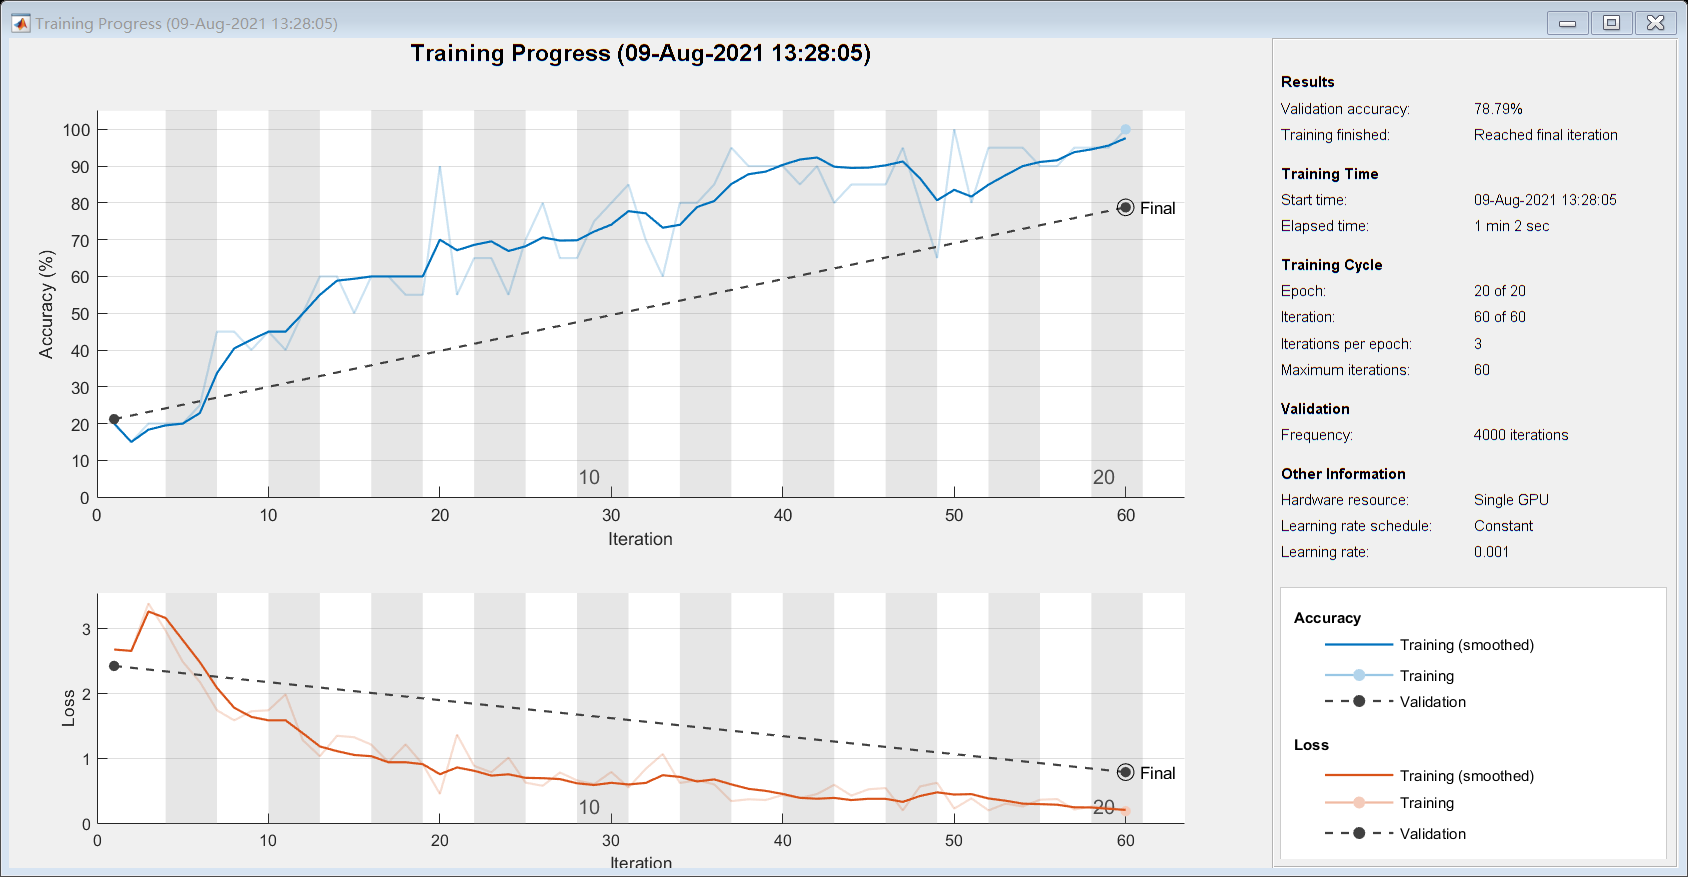

[net, traininfo] = trainNetwork(augimdsTrain,lgraph,opts);